modelName = 'TA1415';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')

p = sdo.getParameterFromModel(modelName,'stepTime');

p.Value = 0;
p.Minimum = 0;
p.Maximum = 15;
p.Scale = 15;
p.Free = 1;


options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

IPASignal = Simulink.SimulationData.Signal;
IPASignal.Name = 'IPA';
IPASignal.BlockPath = modelName + "/Demux";
IPASignal.PortType = 'outport';
IPASignal.PortIndex = 5;
IPASignal.Values = timeseries((1:69)',(1:69)');

Exp.OutputData = IPASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -44.6660

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 22-Mar-2023 22:06:20

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      2      -44.666            0
    1      6     -58.3118            0          0.7         62.6
    2     11     -58.6558            0        0.172         1.28
    3     14     -59.2444            0       0.0473         9.62
    4     18     -59.4446            0       0.0708         8.86
    5     21     -59.5062            0       0.0339         2.38
    6     24     -59.5226            0      0.00719        0.412
    7     27     -59.5242            0       0.0015       0.0304
    8     28     -59.5242            0     7.22e-05       0.0304
局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされているため、
fmincon は停止しました。
 
optInput =
 
       Name: 'stepTime'
      Value: 9.3051
    Minimum: 0
    Maximum: 15
       Free: 1
      Scale: 15
       Info: [1×1 struct]

 
1x1 

optInputInfo = フィールドをもつ struct :
               F: -59.5242
       Gradients: [1×1 struct]
        exitflag: 2
      iterations: 8
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 13.139443 秒です。


maxIPA_TA1415 = -optInputInfo.SolverOutput.fval

maxIPA_TA1415 = 59.5242

SetPointValues = 0:0.1:15;
spv_length = length(SetPointValues);
for i = spv_length:-1:1
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setBlockParameter(modelName + "/To optimize input",...
        'Time',num2str(SetPointValues(i)));
end


out = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[22-Mar-2023 22:06:40] シミュレーションの実行中...
[22-Mar-2023 22:06:41] シミュレーション実行 1/151 が完了
[22-Mar-2023 22:06:42] シミュレーション実行 2/151 が完了
[22-Mar-2023 22:06:43] シミュレーション実行 3/151 が完了
[22-Mar-2023 22:06:43] シミュレーション実行 4/151 が完了
[22-Mar-2023 22:06:44] シミュレーション実行 5/151 が完了
[22-Mar-2023 22:06:44] シミュレーション実行 6/151 が完了
[22-Mar-2023 22:06:45] シミュレーション実行 7/151 が完了
[22-Mar-2023 22:06:45] シミュレーション実行 8/151 が完了
[22-Mar-2023 22:06:45] シミュレーション実行 9/151 が完了
[22-Mar-2023 22:06:46] シミュレーション実行 10/151 が完了
[22-Mar-2023 22:06:46] シミュレーション実行 11/151 が完了
[22-Mar-2023 22:06:47] シミュレーション実行 12/151 が完了
[22-Mar-2023 22:06:47] シミュレーション実行 13/151 が完了
[22-Mar-2023 22:06:47] シミュレーション実行 14/151 が完了
[22-Mar-2023 22:06:48] シミュレーション実行 15/151 が完了
[22-Mar-2023 22:06:48] シミュレーション実行 16/151 が完了
[22-Mar-2023 22:06:49] シミュレーション実行 17/151 が完了
[22-Mar-2023 22:06:49] シミュレーション実行 18/151 が完了
[22-Mar-2023 22:06:50] シミュレーション実行 19/151 が完了
[22-Mar-2023 22:06:50] シミュレーション実行 20/151 が完了
[22-Mar-2023 22:06:50] シミュレーション実行 21/151 が完了
[22-Mar-2023 22:06:51] シミ

out = 1x151 Simulink.SimulationOutput 配列



Bfinal = zeros(spv_length,2);
Bfinal(:,1) = SetPointValues;
for i = spv_length:-1:1
    Bfinal(i,2) = out(i).yout{1}.Values.Data(end);
end

IPAfinal = zeros(15,2);
IPAfinal(:,1) = [0 6 9 12 15 ...
                    0 6 9 12 15 ...
                    0 6 9 12 15]';
for expIdx = 1:15
    a = readtable("TA1415Data.xlsx","Sheet",expIdx);
    IPAfinal(expIdx,2) = a.IPA(end);
end

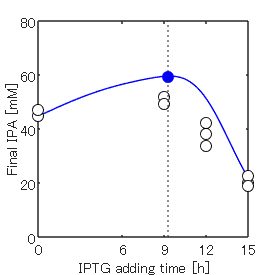

figure('Position', [100 100 200 200]);
plot(Bfinal(:,1),Bfinal(:,2),'b-')
xline(optInput.Value,':')
ylim([0 80])
xlabel('IPTG adding time [h]')
xticks([0 6 9 12 15])
yticks([0 20 40 60 80])
ylabel('Final IPA [mM]')
hold on
plot(optInput.Value,maxIPA_TA1415,'bo','MarkerFaceColor','b')
plot(IPAfinal(:,1),IPAfinal(:,2),'ko','MarkerFaceColor','w')
hold off

% set(gca,'xscale','log')

sdo.setValueInModel(modelName,optInput);